testImageIdx = randi([1,3]);
testCoinImage = imread("testCoinImage"+testImageIdx+".png");

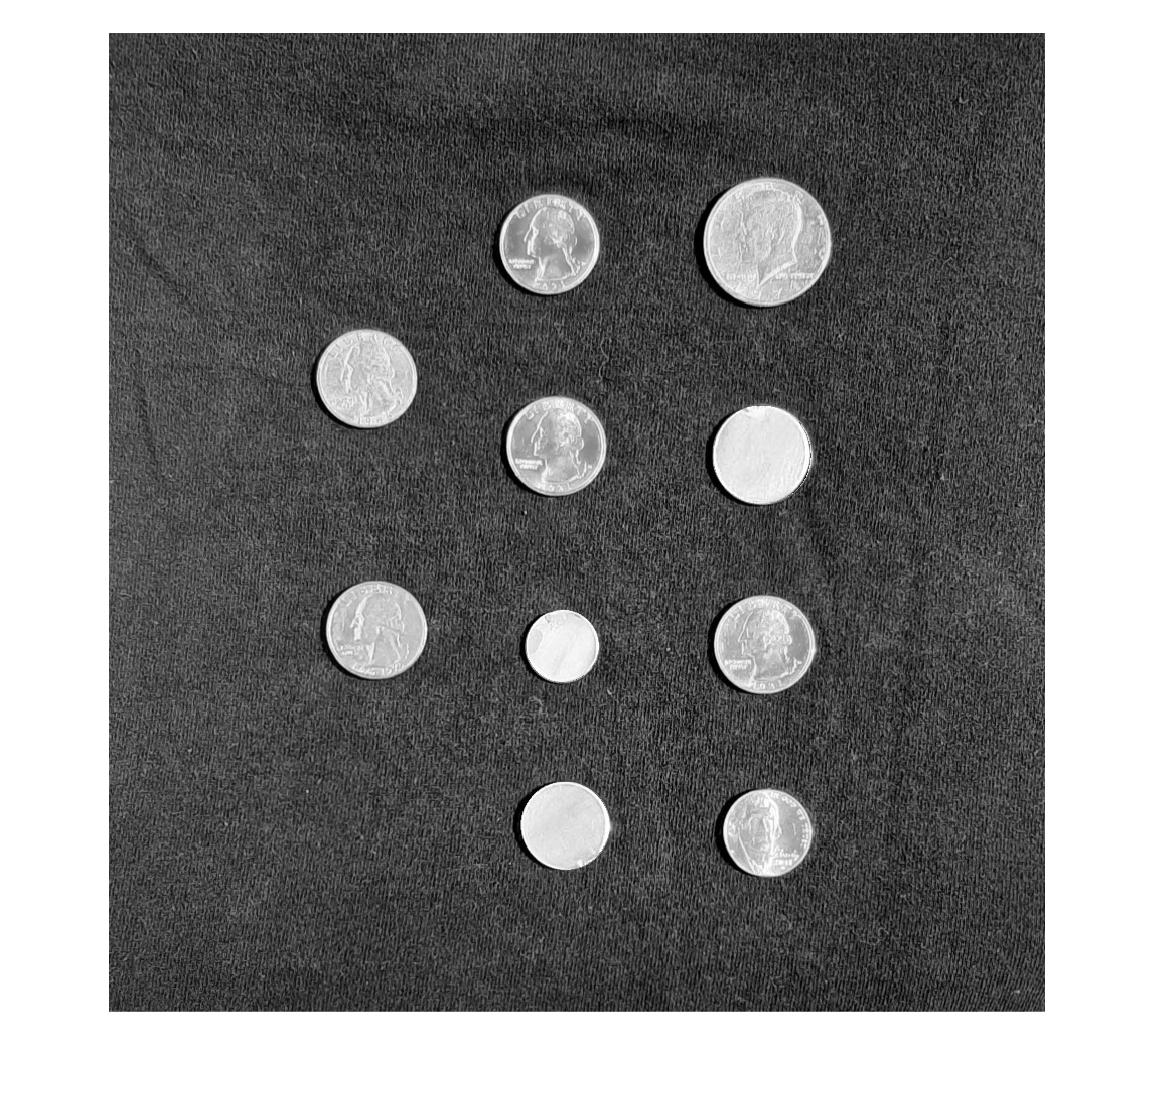

figure, imshow(testCoinImage)

% Create Mask
imgray = imadjust(testCoinImage);
BW = imbinarize(im2gray(imgray), 'adaptive', 'Sensitivity', 0.190000, 'ForegroundPolarity', 'bright');
BW = imfill(BW, 'holes');
radius = 13;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);
radius = 13;
decomposition = 0;
se = strel('disk', radius, decomposition);
testCoinMask = imclose(BW, se);
maskedTestCoinImage = testCoinImage;
maskedTestCoinImage(~testCoinMask) = 0;

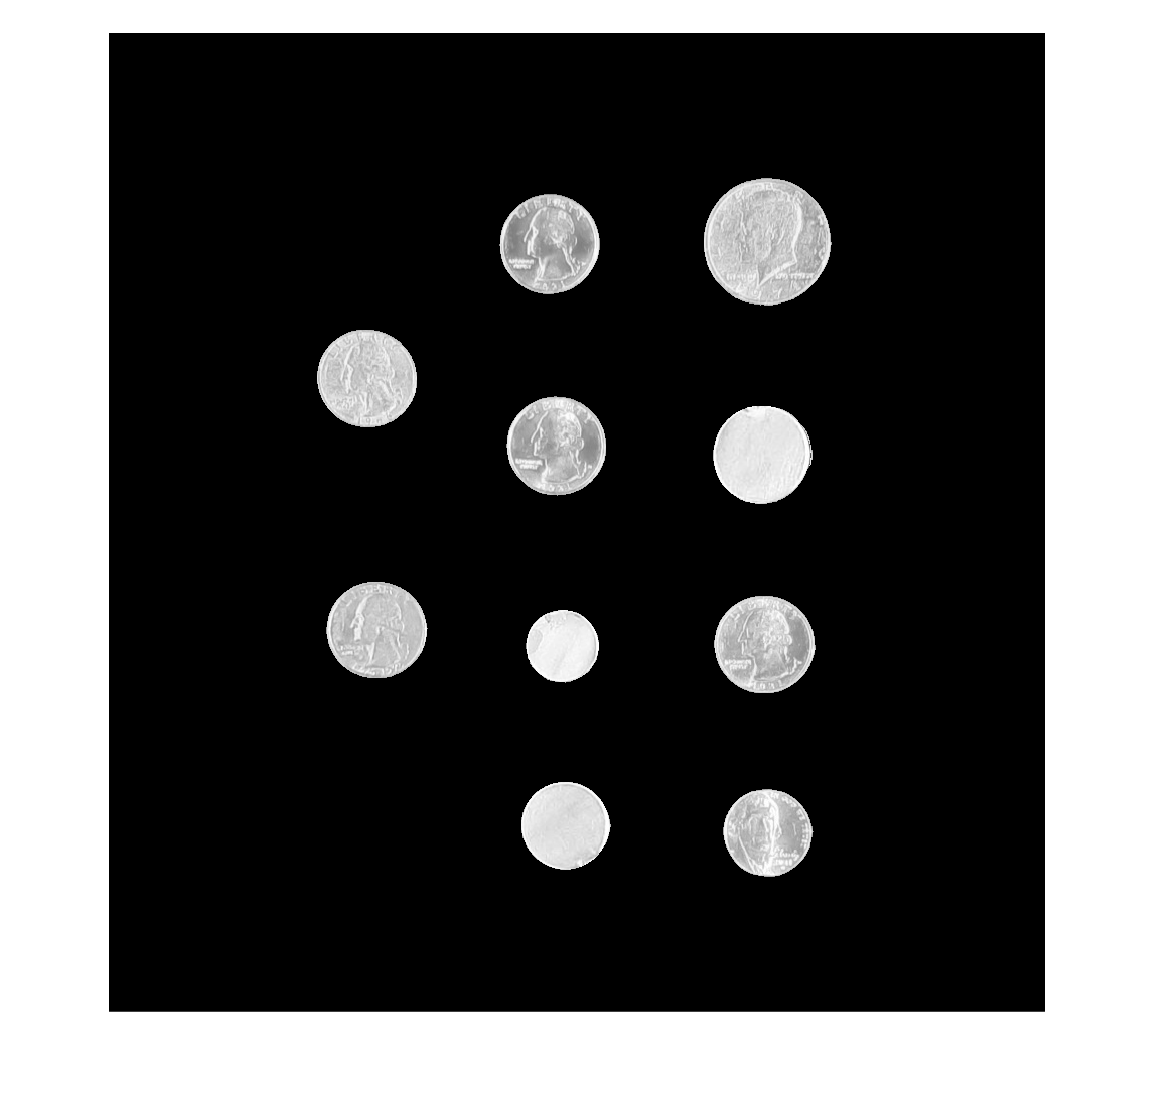

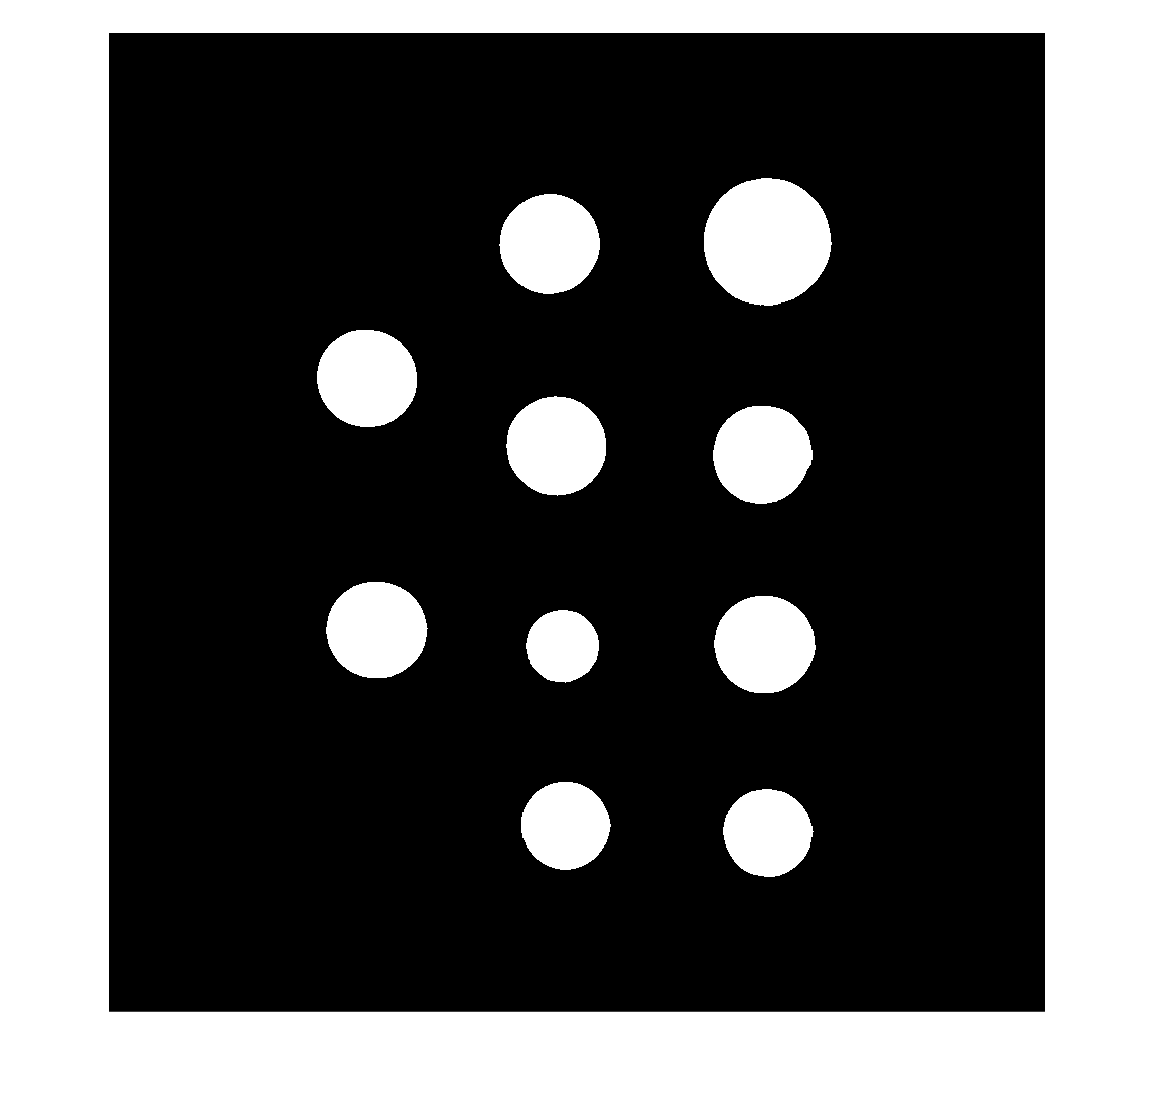

% Eliminate Edges
edgeMask = edge(maskedTestCoinImage,"sobel");

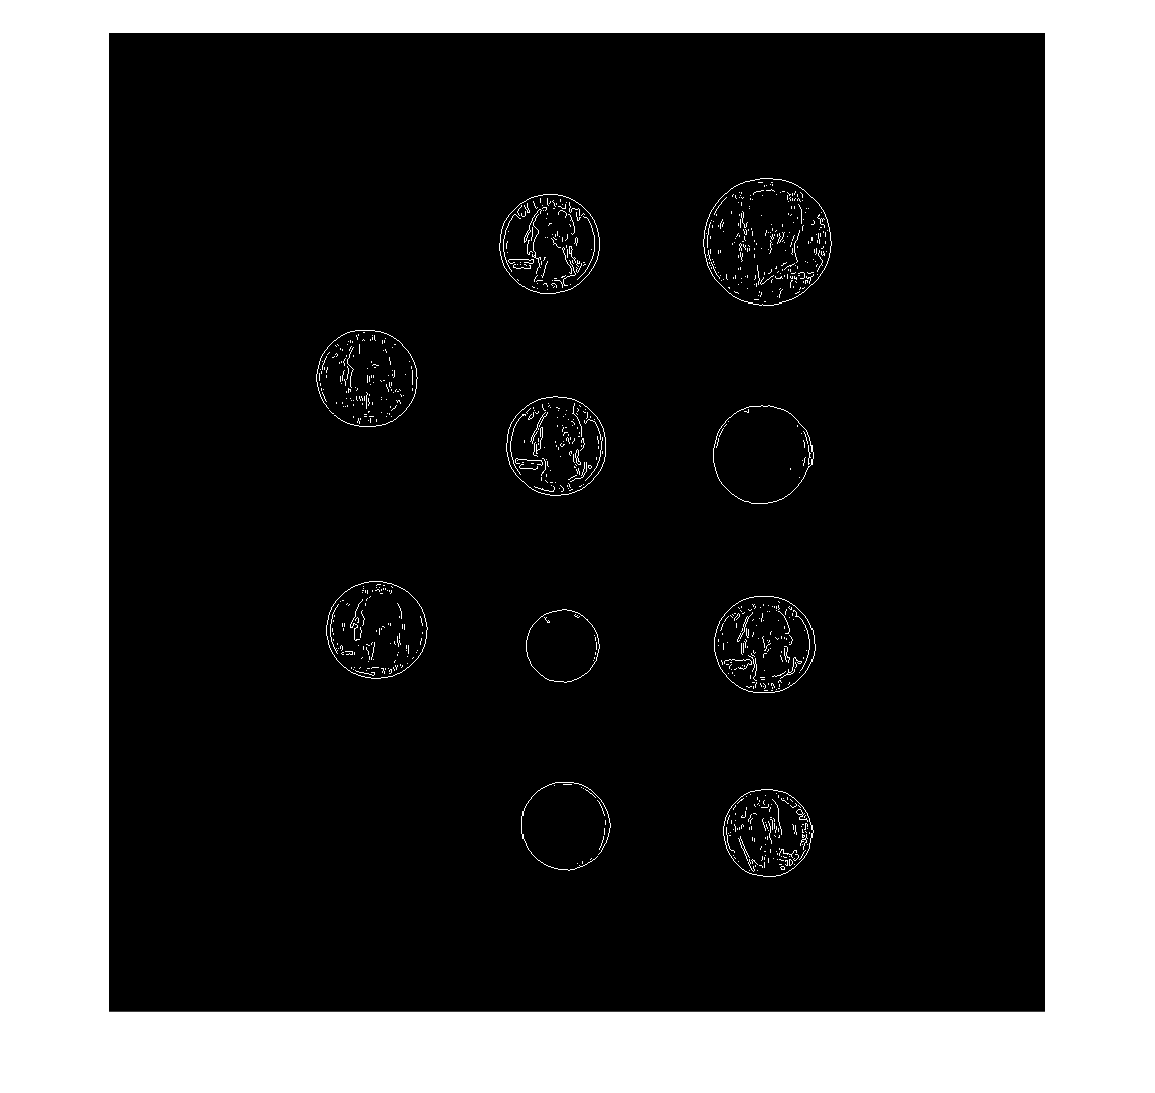

radius = 20;

se = strel('disk', radius, 0);
erodedMask = imerode(testCoinMask, se);
faceEdgeMask = erodedMask & edgeMask;

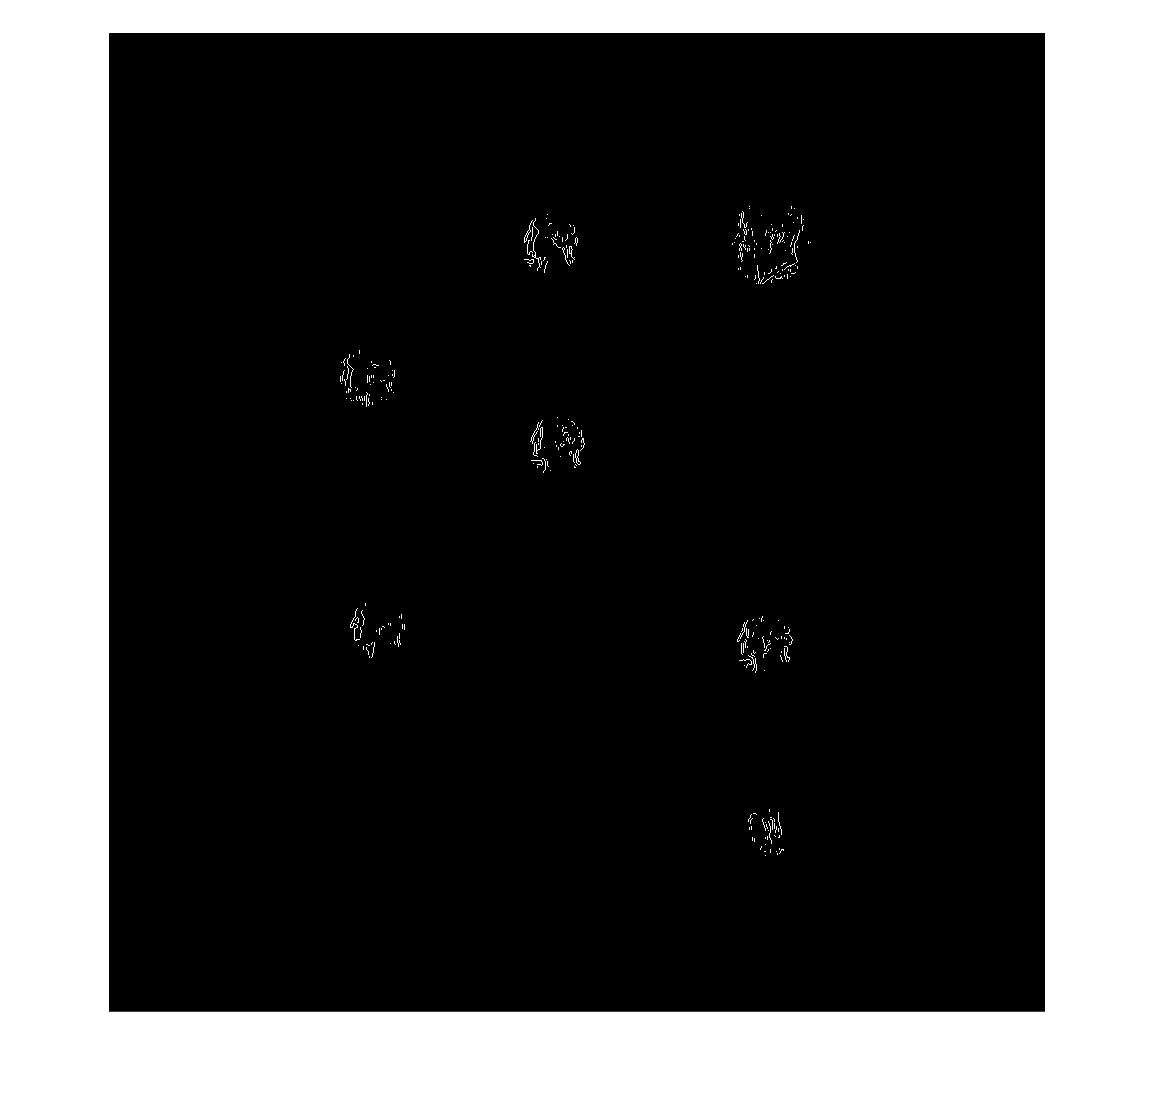

imshow(faceEdgeMask)

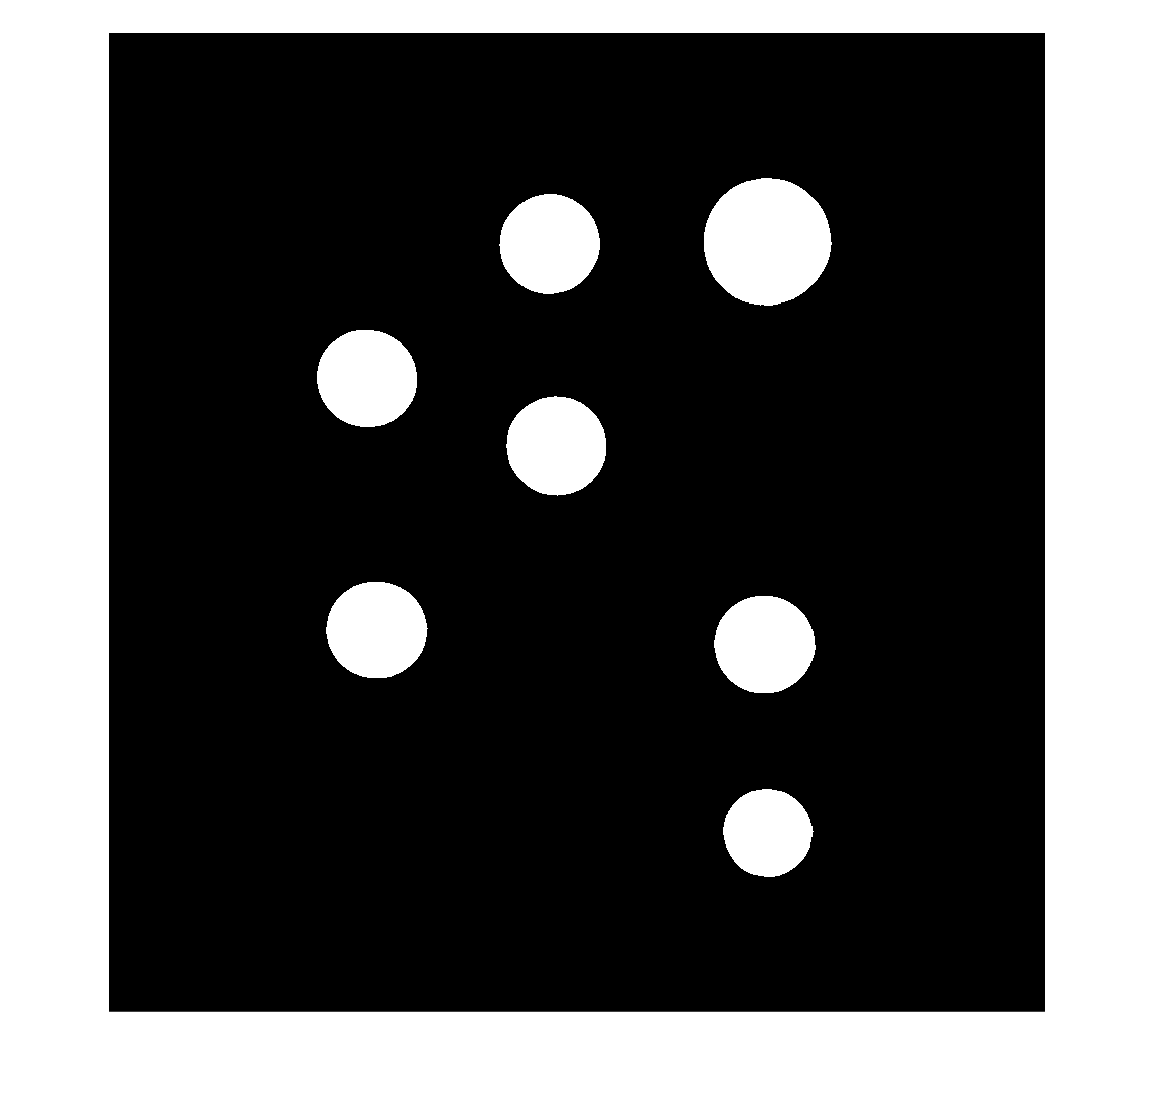

dilateMask = imdilate(faceEdgeMask, strel('disk', 40, 0));
validCoinMask = dilateMask & testCoinMask;
imshow(validCoinMask)

maskedImage = maskedTestCoinImage;
maskedImage(~validCoinMask) = 0;

nFiftyCents = length(regionprops(bwpropfilt(validCoinMask, "Area", [10000, 15000]),{"Area"}));
nQuarters = length(regionprops(bwpropfilt(validCoinMask, "Area", [7000, 8000]), {"Area"}));
nNickels = length(regionprops(bwpropfilt(validCoinMask, "Area", [5000, 7000]), {"Area"}));
nDimes = length(regionprops(bwpropfilt(validCoinMask, "Area", [4000, 5000]), {"Area"}));
USD = nFiftyCents * 0.5 + nQuarters * 0.25 + nNickels * 0.05 + nDimes * 0.1;

USD

USD = 1.8000

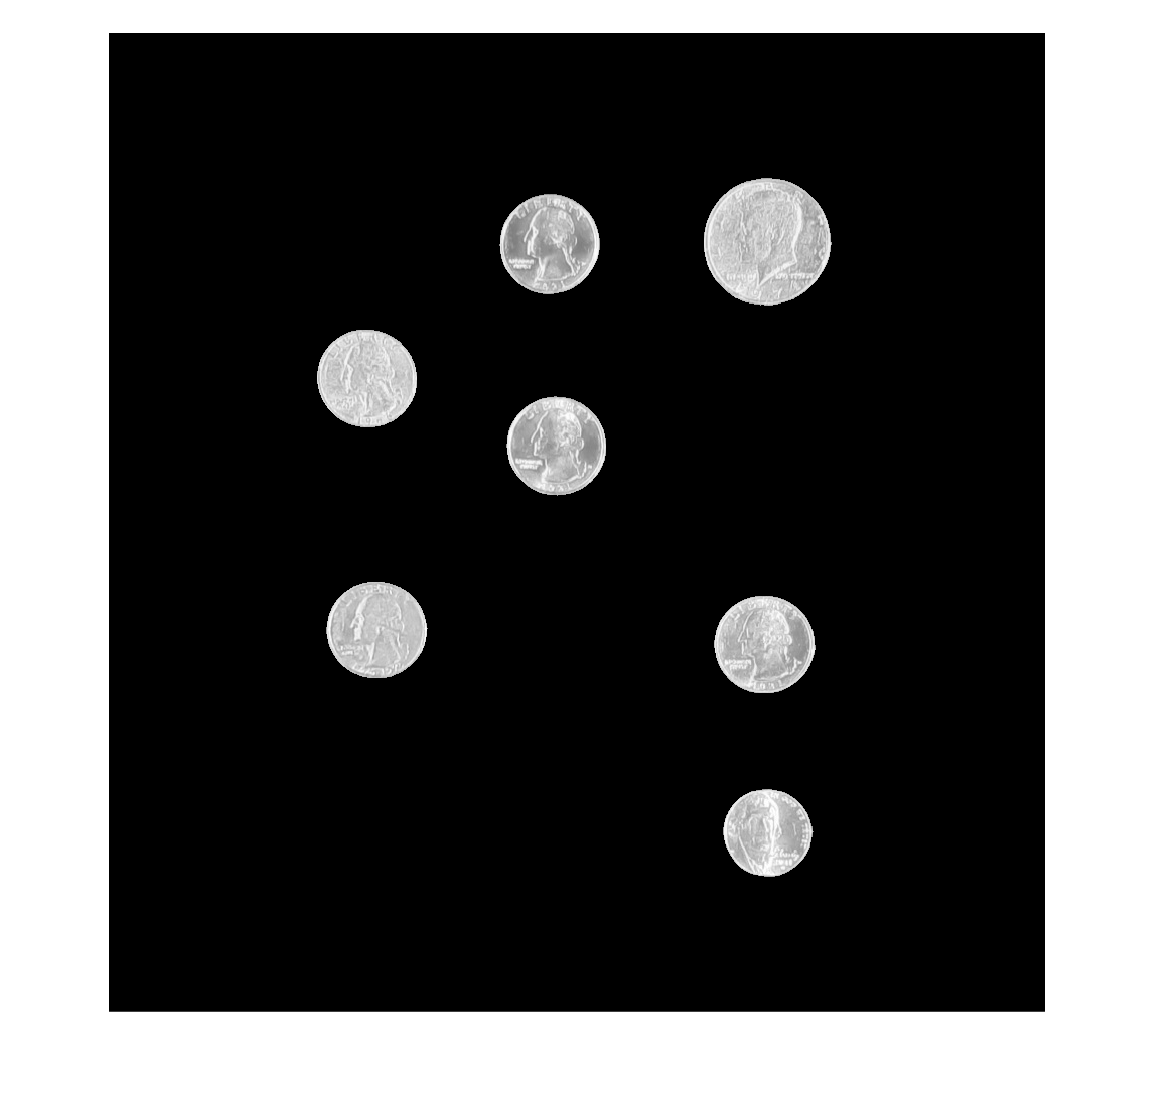

imshow(maskedImage)

img = imread("image.png");

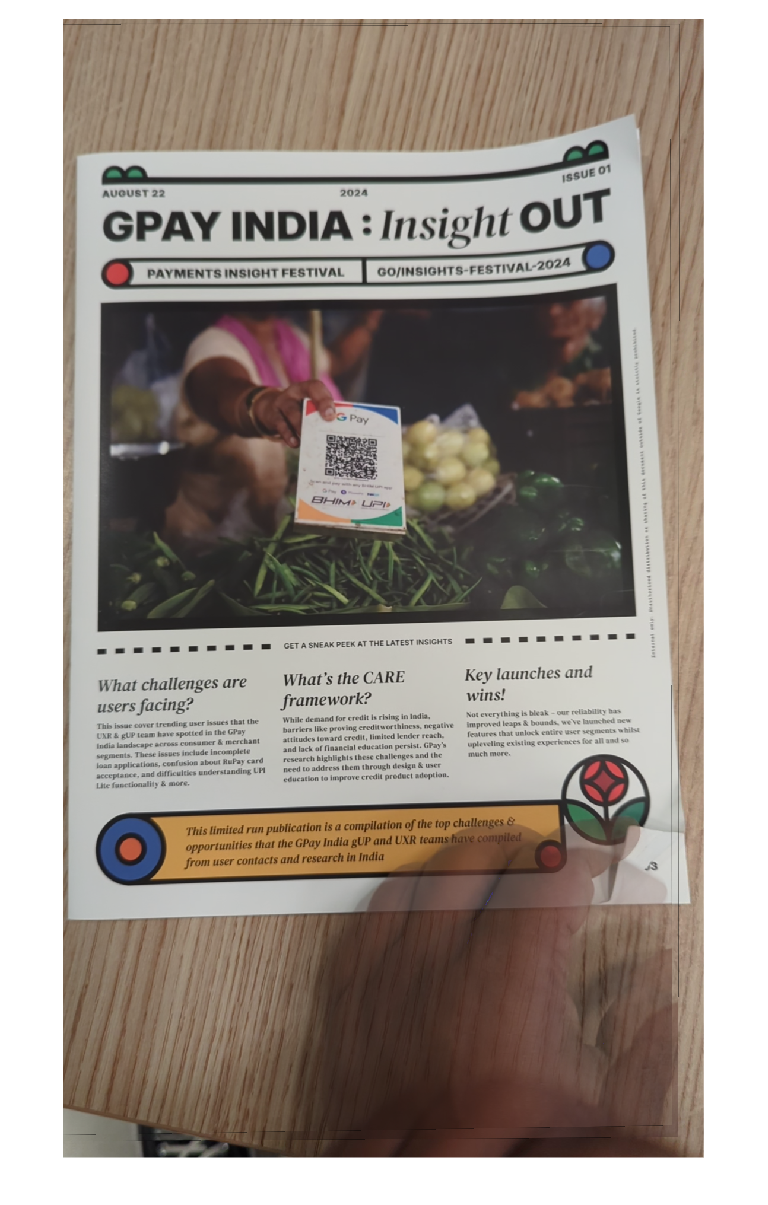

imshow(img)

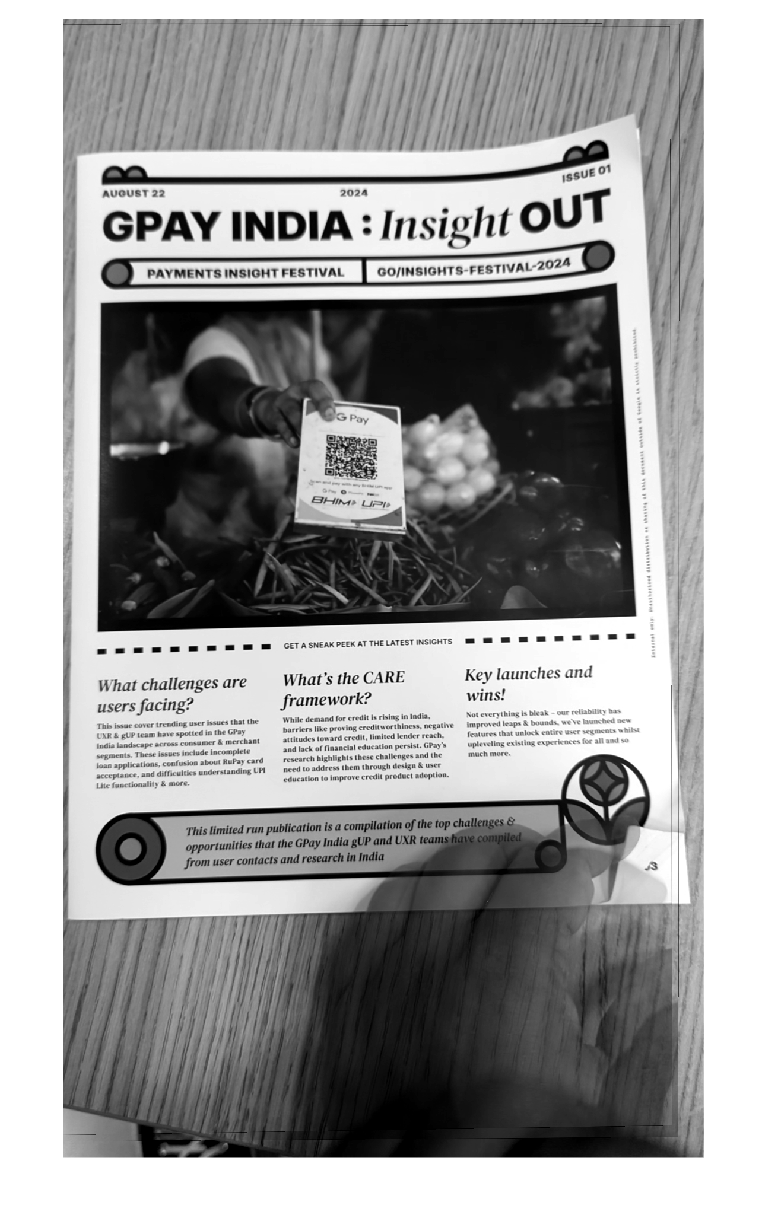

imgray = imadjust(im2gray(img));
imshow(imgray)

BW = imbinarize(imgray, 'adaptive', 'Sensitivity', 0.4, 'ForegroundPolarity', 'bright');

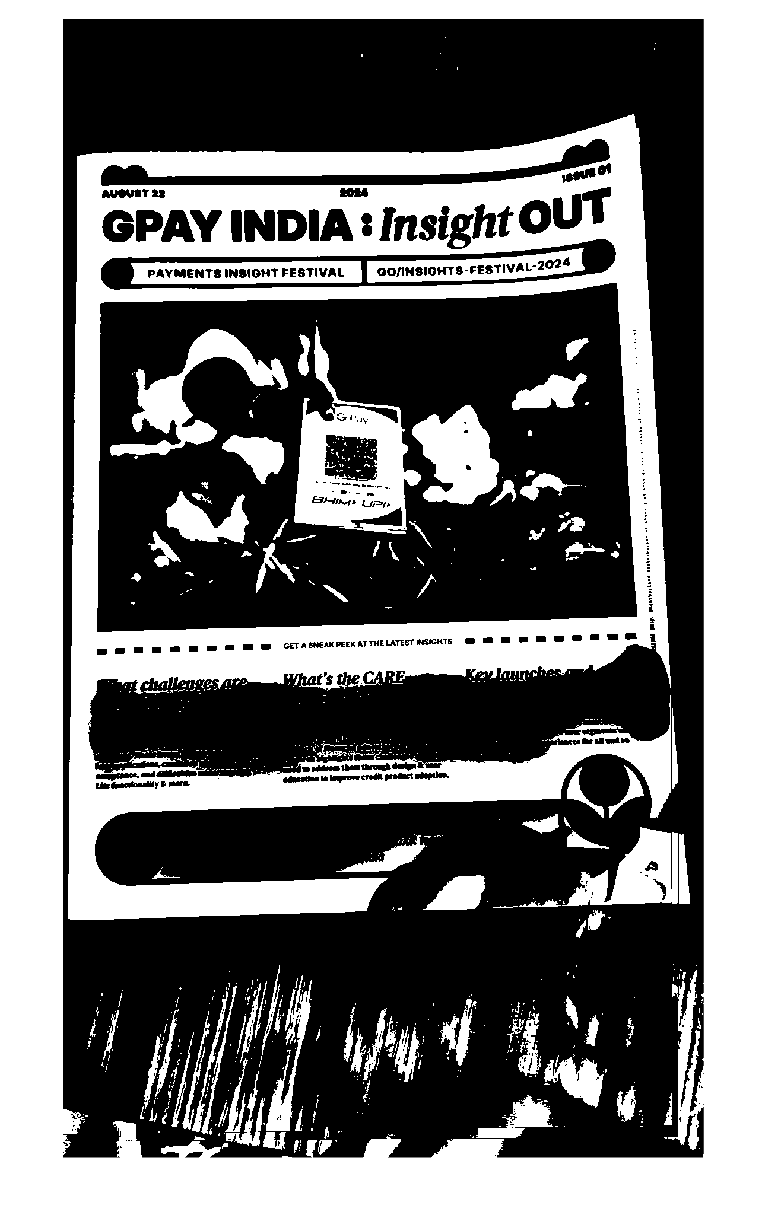


imshow(BW)